# 実行順序の制御と表示

#### 1セクション毎に内容を確認しながら進めてください。ｃｔｒｌ＋Enterです。

## 標準モデルの実行

レートの設定

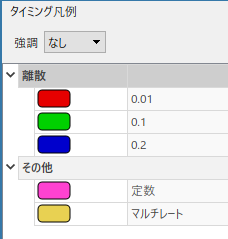

モデルの左側に遅いレート（0.02）、右側が最速レート（0.01）

それを直列に結合した特殊なモデルを作成した。

% モデルを開く
open_system("timebasedmodel0.slx");
% サンプリングカラーの設定をしておく
set_param(bdroot,'SampleTimeColors','on')
% 実行後のビューワー設定　クリアを発行
Simulink.sdi.clear;
Simulink.sdi.clearPreferences;
Simulink.sdi.close;
% シミュレーションを実行
sim("timebasedmodel0.slx");
% 結果を保存
save('matlog_model0.mat','logsout_model0');

Simulink.sdi.view;
Simulink.sdi.setSubPlotLayout(2, 1);

RunIDs = Simulink.sdi.getAllRunIDs;
RunID = Simulink.sdi.getRun(RunIDs(end));

sigID = RunID.getSignalIDsByName('Out1');
sigHD = RunID.getSignal(sigID);
sigHD.plotOnSubPlot(1, 1, true);

sigID = RunID.getSignalIDsByName('Out2');
sigHD = RunID.getSignal(sigID);
sigHD.plotOnSubPlot(1, 1, true);

sigID = RunID.getSignalIDsByName('Out3');
sigHD = RunID.getSignal(sigID);
sigHD.plotOnSubPlot(1, 1, true);


% 一旦停止
q_ans=questdlg({'モデルの表示を確認して先に進んでください。','先に進みますか'});
if ~strcmp(q_ans,'Yes') 
    return;
end


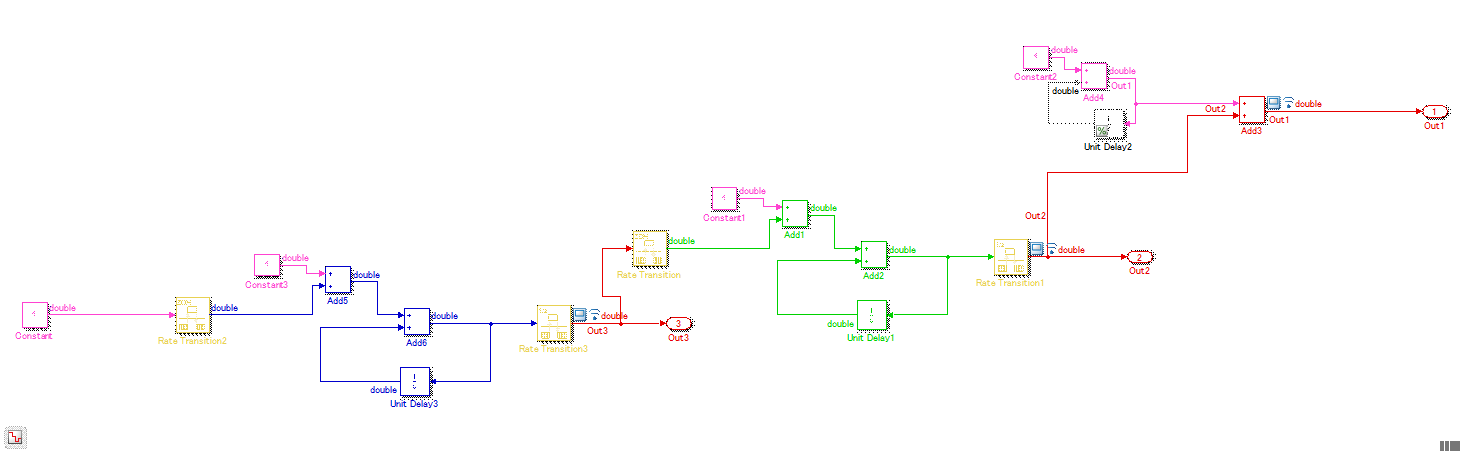

実行順序の表示

【デバッグ】のタブから、実行順序を選択する

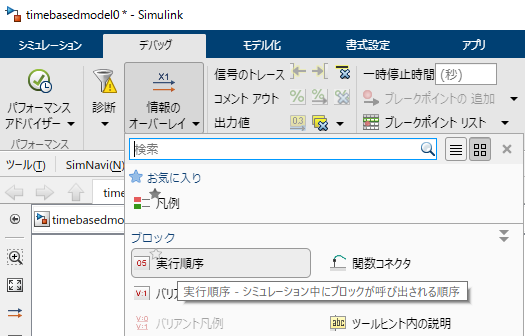

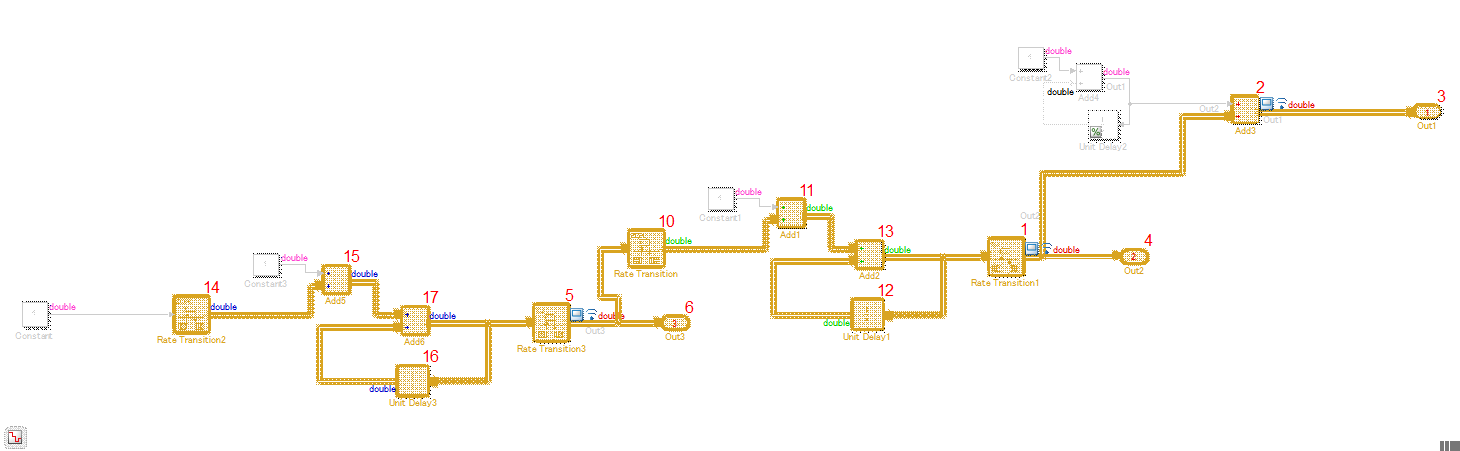

見ての通り、標準では早いレートが優先されて、遅いレートが後で計算されるので、この場合はモデルの流れと

実行順序は逆になる。

%% 上記の絵が表示されるであろうコマンドを下に記載するが、
% 残念ながら人の手によるウインドウ操作じゃないと表示されません
set_param(bdroot,'SampleTimeColors','off');
set_param(bdroot,'SortedOrder','on')
set_param(bdroot,'DisplaySortedLists','on')


 sim("timebasedmodel0.slx");


---- Sorted list for 'timebasedmodel0' [24 nonvirtual block(s), directFeed=0]
     Total number of tasks = 2
- Sorted list of task index [0], 20 nonvirtual block(s)
  (0)0:1   'timebasedmodel0/Unit Delay2' (UnitDelay)
          Input ports:  [0]
          Output ports: [0]
  (0)0:2   'timebasedmodel0/Add4' (Sum)
          Input ports:  [0 1]
          Output ports: [0]
  (0)0:3   'timebasedmodel0/Rate Transition1' (RateTransition)
          Input ports:  [0]
          Output ports: [0]
  (0)0:4   'timebasedmodel0/Add3' (Sum)
          Input ports:  [0 1]
          Output ports: [0]
  (0)0:5   'timebasedmodel0/Out1' (Outport)
          Input ports:  [0]
          Output ports: []
  (0)0:6   'timebasedmodel0/Out2' (Outport)
          Input ports:  [0]
          Output ports: []
  (0)0:7   'timebasedmodel0/Rate Transition3' (RateTransition)
          Input ports:  [0]
          Output ports: [0]
  (0)0:8   'timebasedmodel0/Out3' (Outport)
          Input ports:  [0]
          Output port

 
RunIDs = Simulink.sdi.getAllRunIDs;
RunID = Simulink.sdi.getRun(RunIDs(end));

sigID = RunID.getSignalIDsByName('Out1');
sigHD = RunID.getSignal(sigID);
sigHD.plotOnSubPlot(2, 1, true);

sigID = RunID.getSignalIDsByName('Out2');
sigHD = RunID.getSignal(sigID);
sigHD.plotOnSubPlot(2, 1, true);

sigID = RunID.getSignalIDsByName('Out3');
sigHD = RunID.getSignal(sigID);
sigHD.plotOnSubPlot(2, 1, true);

% 一旦停止
q_ans=questdlg({'モデルの表示を確認して先に進んでください。','先に進みますか'});
if ~strcmp(q_ans,'Yes') 
    return;
end

## 優先順位の変更

addブロックの優先順位を変更し、モデルの構成に合わせた実行順序に変更した。

Rate Transition にも設定してある。

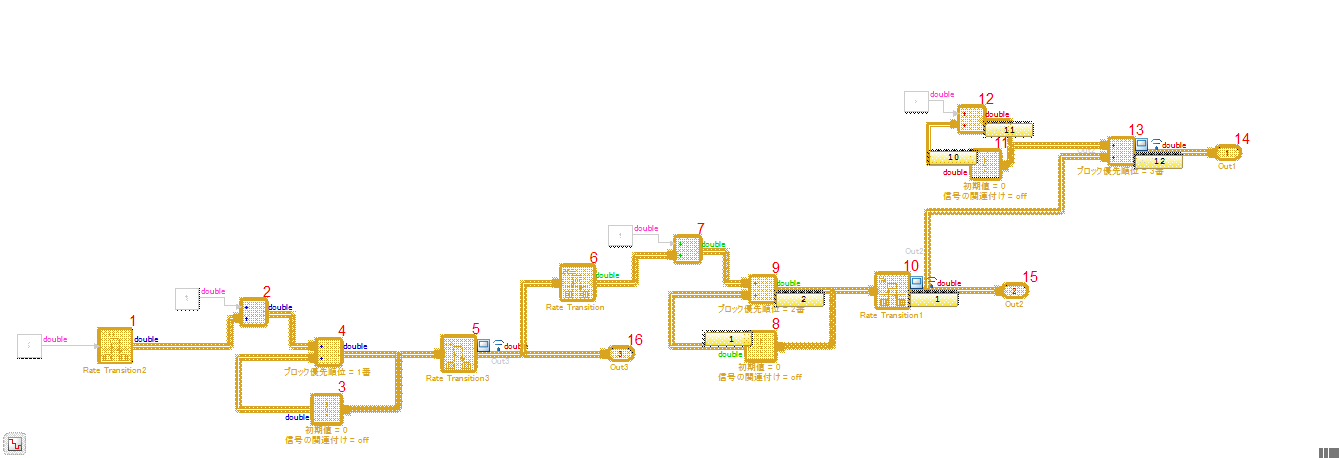　

open_system("timebasedmodel1.slx");
set_param(bdroot,'SampleTimeColors','on')
sim(bdroot);
save('matlog_model1.mat','logsout_modle1');
q_ans=questdlg({'モデルの表示を確認して先に進んでください。','先に進みますか'});
if ~strcmp(q_ans,'Yes') 
    return;
end

## 結果

out3の入力値が１周期前後するため、結果に違いが生じる。

%% ビューワー表示　自分で設定して使って
Simulink.sdi.view


### デバッグモードで比較する

#### モデル１

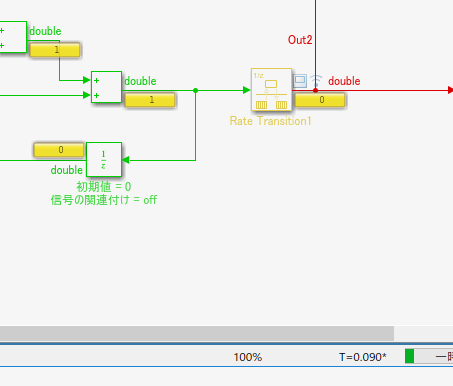　

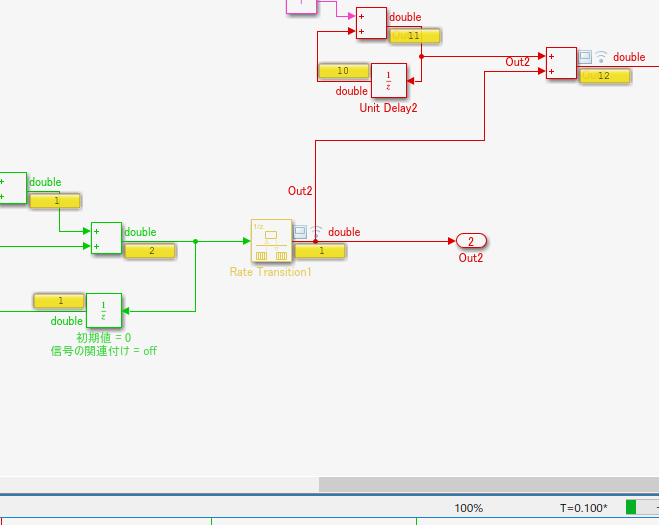

#### モデル２

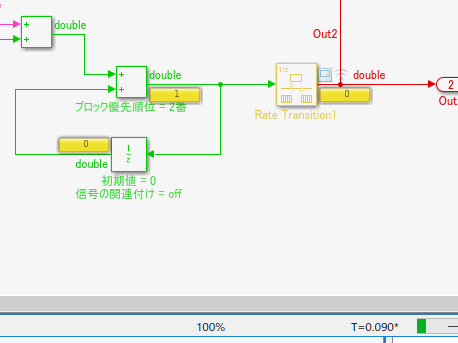　

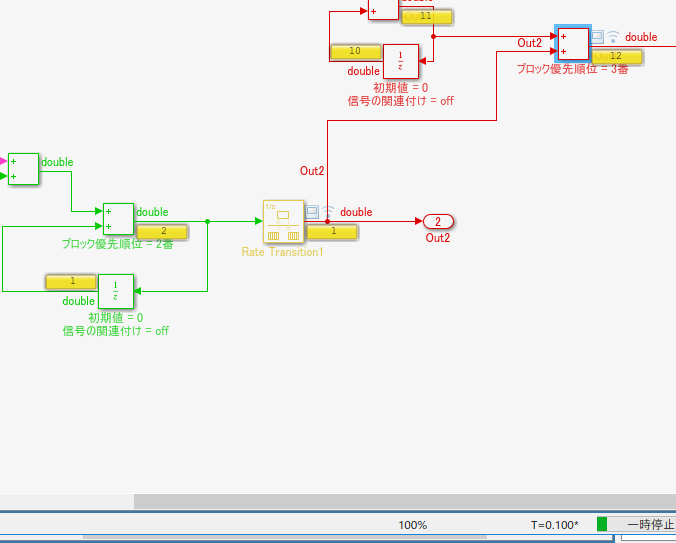

実行順序の設定を行ったが、Rate Transitonがタイミングのずれを吸収し、

結果には影響を及ぼさないようになっている。

## コンフィギュレーションの影響

### 元々のコンフィギュレーション

周期的なサンプル時間に制約　：　制約なし

各離散レートを個別のタスクとして扱う　チェックなし。

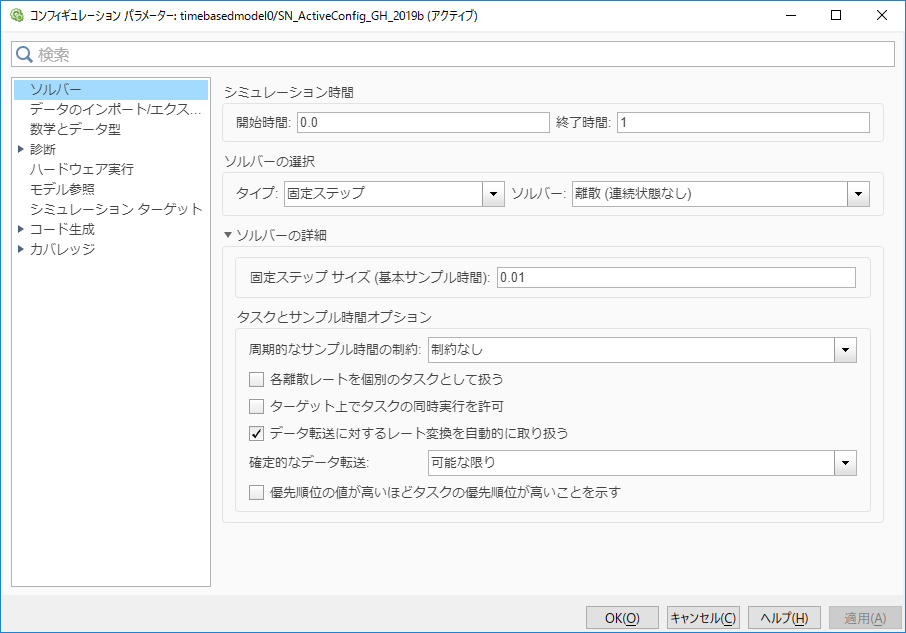

### レートを個別指定

上の評価同様に、レートが遅い周期の優先順位を上げる。

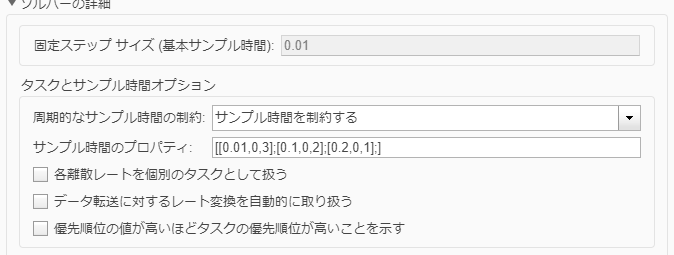

実行順序を表示すると、同上と同じように左側に置いたレートの遅い物の実行順序が早くなった。

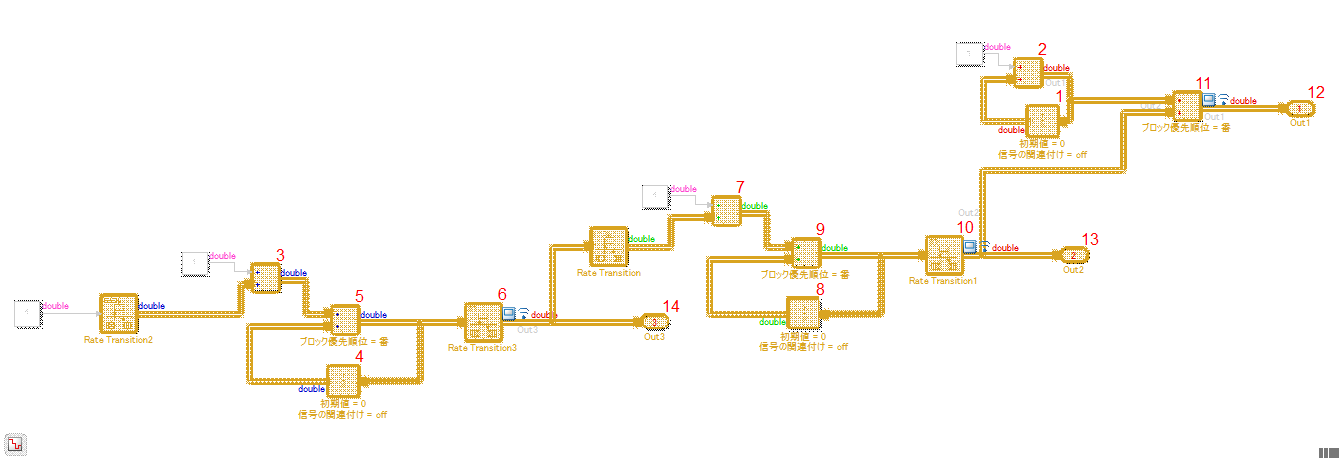

open_system("timebasedmodel2.slx");
set_param(bdroot,'SampleTimeColors','on')
sim(bdroot);

save('matlog_model2.mat','logsout_modle2');
q_ans=questdlg({'モデルの表示を確認して先に進んでください。','先に進みますか'});
if ~strcmp(q_ans,'Yes') 
    return;
end

timebasedmodel1の１回目の実行結果

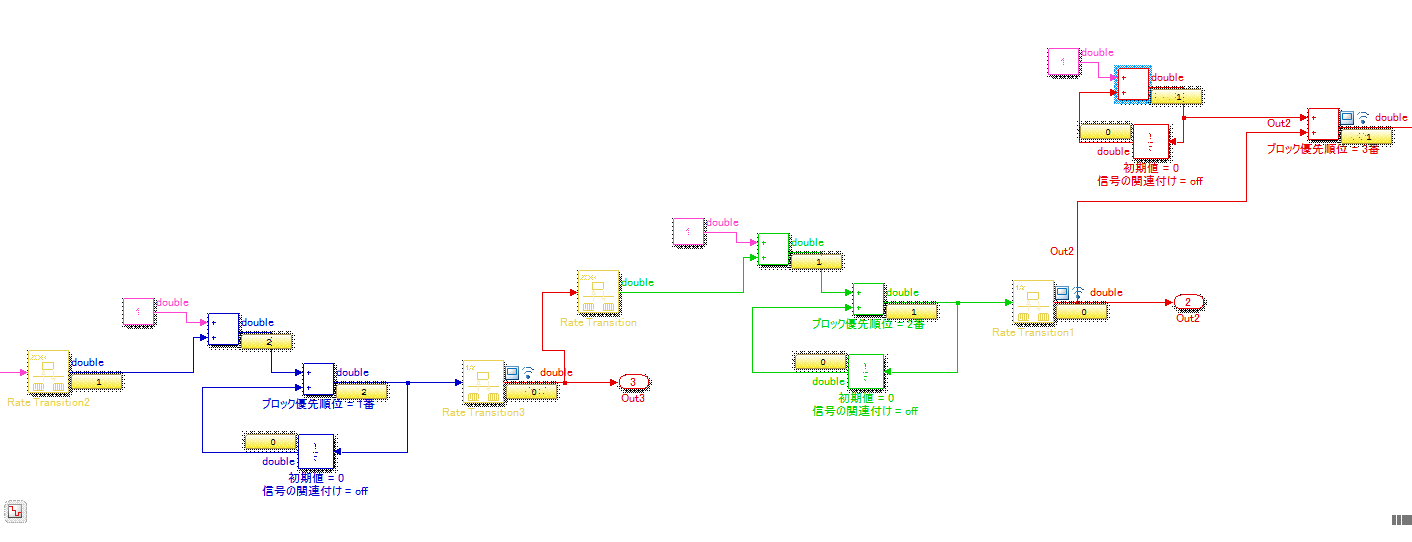

timebasedmodel2の実行結果

Rate Tranjitionが仕事をしていません。

データも一部最適化で削除されているのが良くわかる。

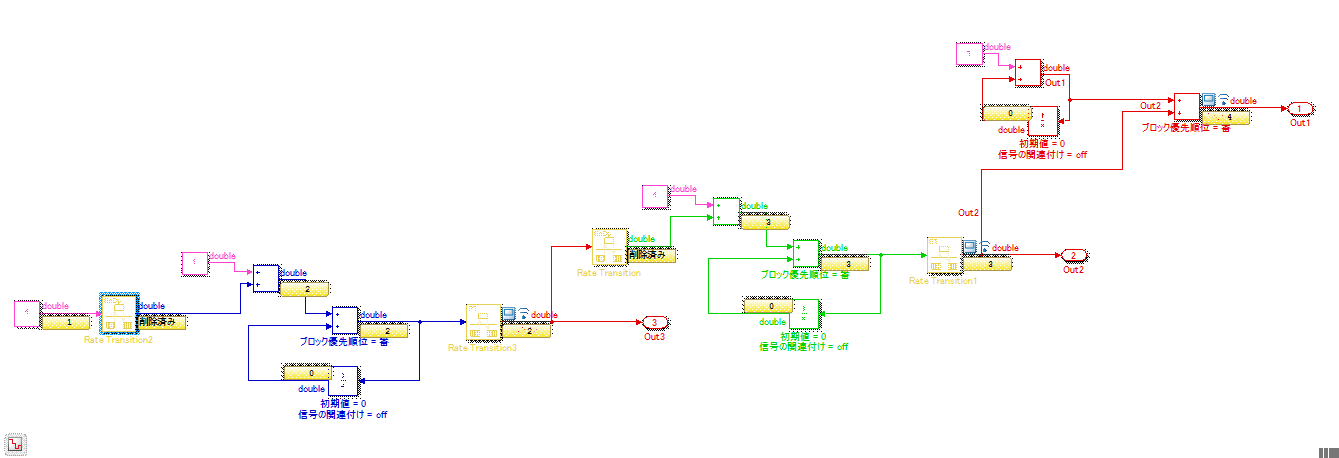

## コンフィギュレーションの影響

先ほどのコンフィギュレーションは、実行結果に影響を及ぼしたが、実行順序の表示には影響を及ぼさなかったので、

元のtimebasedmodel0に対して、各離散レートを個別のタスクとして扱うをチェックする

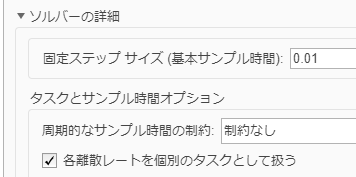

open_system("timebasedmodel3.slx");
set_param(bdroot,'SampleTimeColors','on')
sim("timebasedmodel3.slx");

'timebasedmode3.slx' というシステムもファイルも見つかりません。

save('matlog_model3.mat','logsout_model3');
q_ans=questdlg({'モデルの表示を確認して先に進んでください。','先に進みますか'})
if ~strcmp(q_ans,'Yes') 
    return;
end

### 実行順序の表示

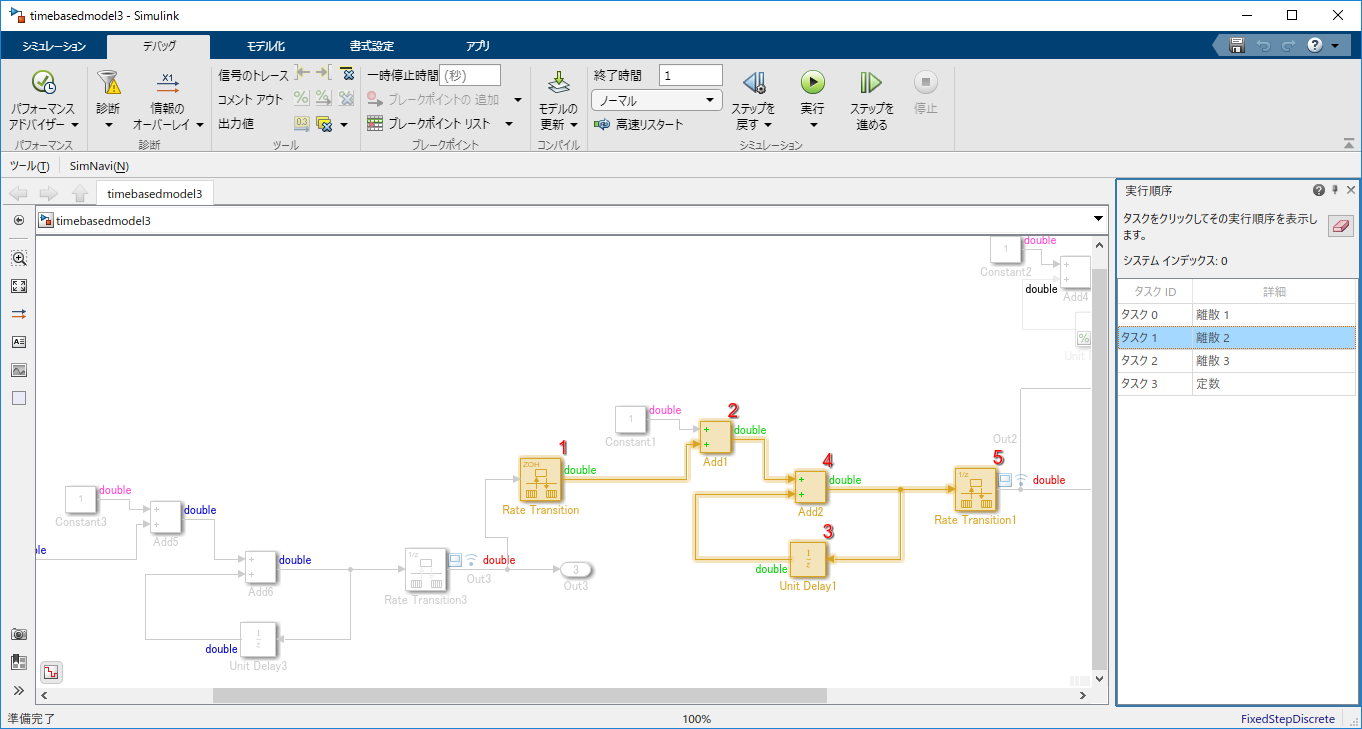

タスクの選択を切り替えると、表示が変わっていく。

タスク間の実行順序は示せないが、強引なレート設定を行わない限りは、タスク間の表示に意味が無い

（Rate Tranjitionが更新タイミングを調整するので、タスク間の実行タイミングは前後しても結果に影響が出にくい）